# Windkessel model

Copyright (C) [2020](#2020)  [Bolic](#Miodrag)

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES.

### Acknowledgements: 

## Introduction

In this section Windkessel model will be presented. 

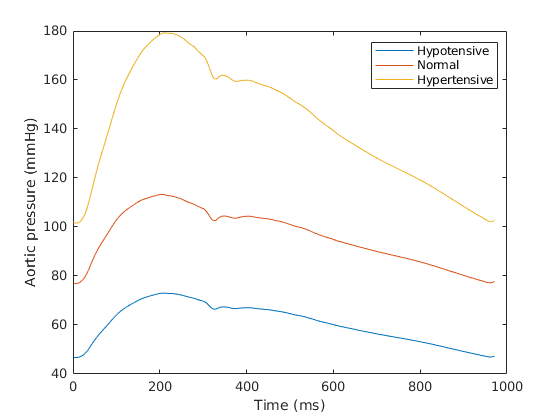

% Modeling Case 1

load('data_17s.mat')
a=[];
fs=200;
src1=zeros(200,0);
global start_pulse_ind;
global end_pulse_ind;
start_pulse_ind=15800;
end_pulse_ind=16841;
%src1=240*ones(65,1);
inp1(:,2)=TFP(:,2);
inp1(:,1)=TFP(:,1);
model_name = 'WK';
open_system(model_name)
param=[0.02 2 0.6 0.005; 0.033 1.5 0.95 0.01; 0.05 0.7 1.4 0.02];
%param=[3 2 0.6 0.005];
cases=['hypotensive', 'normotensive', 'hypertensive'];
figure
for level =1:3
   
    
    L = sdo.getParameterFromModel(model_name, 'L');
    L.Value=param(level,4);
    sdo.setValueInModel(model_name,L);
    
    R0 = sdo.getParameterFromModel(model_name, 'R0');
    R0.Value=param(level,1);
    sdo.setValueInModel(model_name,R0);
    
    R = sdo.getParameterFromModel(model_name, 'R');
    R.Value=param(level,3);
    sdo.setValueInModel(model_name,R);
    
    Ca = sdo.getParameterFromModel(model_name, 'Ca');
    Ca.Value=param(level,2);
    sdo.setValueInModel(model_name,Ca);
    
    % Collect these parameters into a vector.
    v = [L R0 R Ca];
    
    simOut = sim(model_name, 'CaptureErrors', 'on');
    %figure
    %plot(simOut.simout.Time, simOut.simout.Data)
    plot(simOut.simout.Data(14000:14970))
    hold on
end
xlabel("Time (ms)")
ylabel("Aortic pressure (mmHg)")
legend({'Hypotensive', 'Normal', 'Hypertensive'},'Location','Best')

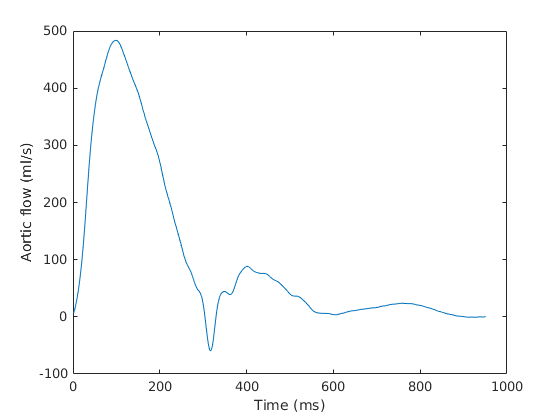


figure
plot(inp1(14000:14950,2))
xlabel("Time (ms)")
ylabel("Aortic flow (ml/s)")


% hold on
% plot()

## Sensitivity analysis and fitting the model

In this section, we will load data that correspond to the flow and pressure of a hypotensive subject with low blood pressure. Then we will perform the following steps:

- Sensitivity analysis to determine the initial values of the parameters for the estimation 

- Selection of parameters that need to be optimized.

- Fitting the parameters of the model.

- Determining the accuracy of the fitting since we already know the parameters for the hypotensive subject. 

Sensitivity analysis

% Modeling Case 2
% Sensitivity analysis
out(:,2)=TFP(:,3);
out(:,1)=TFP(:,1);

[EvalResult, ParamValues, p] = sensitivityEvaluationWK(out)

ps =   ParameterSpace with properties:

            ParameterNames: {'R0'  'Ca'  'R'  'L'}
    ParameterDistributions: [1×4 prob.UniformDistribution]
           RankCorrelation: []
                   Options: [1×1 sdo.SampleOptions]
                     Notes: []


EvalResult = 100×1 table
    CustomReq
    _________

     381.74  
     638.87  
       7580  
     1276.1  
     1794.6  
      571.5  
     5485.5  
     604.77  
       3702  
      42.83  
     1740.3  
     87.641  
     2700.9  
     3351.2  
       1266  
     113.02  


ParamValues = 100×4 table
       R0         Ca          R          L    
    ________    _______    _______    ________

    0.047618     1.6627    0.52658    0.046666
    0.028775     1.9803    0.46395    0.007141
    0.021804      1.179     1.5712     0.04276
    0.022038     2.7898     1.0669    0.028271
    0.042056     2.7087     1.1352    0.028583
    0.091994      1.818     0.9425    0.011982
    0.040271      1.823     1.4461    0.016942
    0.048692    0.86679     0.9369     0.02262
    0.056364     1.0445     1.3129    0.019118
    0.065764     2.4831    0.66392    0.047771
    0.085604      0.518      0.391    0.044329
    0.027378     1.2779    0.64602    0.047307
    0.091046    0.88754    0.21523    0.011383
    0.073331    0.61834    0.16303    0.013113
    0.070355     2.8687    0.36548    0.018527
    0.079328     1.6532    0.80996    

 
p(1,1) =
 
       Name: 'R0'
      Value: 0.0500
    Minimum: 0.0100
    Maximum: 0.1000
       Free: 1
      Scale: 0.0625
       Info: [1×1 struct]

 
p(2,1) =
 
       Name: 'Ca'
      Value: 2
    Minimum: 0.5000
    Maximum: 3
       Free: 1
      Scale: 1
       Info: [1×1 struct]

 
p(3,1) =
 
       Name: 'R'
      Value: 0.6000
    Minimum: 0.1000
    Maximum: 2
       Free: 1
      Scale: 2
       Info: [1×1 struct]

 
p(4,1) =
 
       Name: 'L'
      Value: 0.0050
    Minimum: 1.0000e-03
    Maximum: 0.0500
       Free: 1
      Scale: 0.0312
       Info: [1×1 struct]

 
4x1 param.Continuous
 
lists of methods, superclasses
 


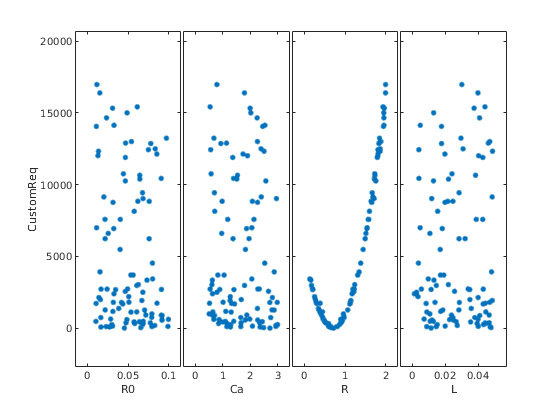


sdo.scatterPlot(ParamValues,EvalResult)

opts = sdo.AnalyzeOptions;
opts.Method = 'Correlation';
sensitivities = sdo.analyze(ParamValues,EvalResult, opts);
disp(sensitivities)

          CustomReq
          _________

    R0     -0.13846
    Ca    -0.031631
    R       0.85271
    L      0.025048



Selection of parameters

[fval, idx_min] = min(EvalResult.CustomReq);
L.Value = ParamValues.L(idx_min);
R0.Value = ParamValues.R0(idx_min);
R.Value = ParamValues.R(idx_min);
Ca.Value = ParamValues.Ca(idx_min);
L.Minimum=L.Value/2;
L.Maximum=L.Value*1.5;

R0.Minimum=R0.Value/2;
R0.Maximum=R0.Value*1.5;

R.Minimum=R.Value/2;
R.Maximum=R.Value*1.5;

Ca.Minimum=Ca.Value/2;
Ca.Maximum=Ca.Value*1.5;



Optimization

% Selection of parameters from the sensitivity analysis to be used in the
% optimization
Exp = sdo.Experiment(model_name);
v = [L R0 R Ca];
Exp = setEstimatedValues(Exp, v);   % use vector of parameters/states
Simulator = createSimulator(Exp);
% Simulator = sim(Simulator);
% % Retrieve logged signal data.
% SimLog = find(Simulator.LoggedData,get_param('WK','SignalLoggingName'));
% Sig_Log = find(SimLog,'Sig');


opts = sdo.OptimizeOptions;
opts.Method = 'fmincon';
estFcn = @(v) WK_OptEvalFcn(v, Simulator, Exp,out);
vOpt = sdo.optimize(estFcn, v, opts);


 Optimization started 25-Jun-2021 21:28:29



                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      9      9.83537            0


    1     26      7.86689            0       0.0975          248


    2     36      7.41037            0         1.09          187


    3     52        6.601            0        0.114          369


    4     64      3.72284            0         0.38         45.2


    5     77      2.75152            0        0.386          237


    6     85     0.558928            0        0.632         5.97


    7     94        0.427            0        0.212          2.9


    8    103     0.421071            0       0.0591         5.41


    9    112     0.418591            0        0.119         6.03


   10    121      0.41796            0        0.031         1.69


   11    129     0.417581            0     0.000954       0.0602
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.


disp(vOpt)

 
(1,1) =
 
       Name: 'L'
      Value: 0.0171
    Minimum: 0.0057
    Maximum: 0.0171
       Free: 1
      Scale: 0.0156
       Info: [1×1 struct]

 
(1,2) =
 
       Name: 'R0'
      Value: 0.0375
    Minimum: 0.0228
    Maximum: 0.0684
       Free: 1
      Scale: 0.0625
       Info: [1×1 struct]

 
(1,3) =
 
       Name: 'R'
      Value: 0.7126
    Minimum: 0.3603
    Maximum: 1.0809
       Free: 1
      Scale: 1
       Info: [1×1 struct]

 
(1,4) =
 
       Name: 'Ca'
      Value: 2.1091
    Minimum: 1.3568
    Maximum: 4.0703
       Free: 1
      Scale: 2
       Info: [1×1 struct]

 
1x4 param.Continuous
 
lists of methods, superclasses
 


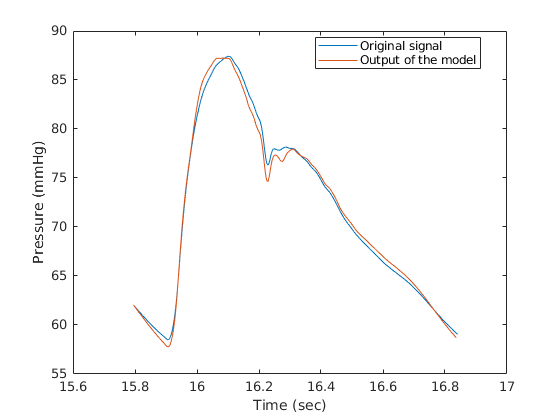



%% Visualizing Result of Optimization
%
% Obtain the model response after estimation.  Search for the
% model_residual signal in the logged simulation data.
Exp = setEstimatedValues(Exp, vOpt);   % use vector of parameters/states
Simulator = createSimulator(Exp);
Simulator = sim(Simulator);

figure
plot(out(start_pulse_ind:end_pulse_ind,1), out(start_pulse_ind:end_pulse_ind,2))
hold on
plot(Simulator.LoggedData.simout.Time(start_pulse_ind:end_pulse_ind), Simulator.LoggedData.simout.Data(start_pulse_ind:end_pulse_ind))
xlabel('Time (sec)');
ylabel('Pressure (mmHg)');
legend({'Original signal', 'Output of the model'},'Location','Best')

function Vals = WK_OptEvalFcn(v,Simulator,Exp,out)
%WK_EVALFCN
%
% Function called at each iteration of the evaluation problem.
%
% The function is called with a set of parameter values, P, and returns
% the evaluated cost, Vals.
%
% See the sdoExampleCostFunction function and sdo.evaluate for a more
% detailed description of the function signature.
%

%% Model Evaluation
%start_pulse_ind=15800;
%end_pulse_ind=16841;
global start_pulse_ind;
global end_pulse_ind;
% Simulate the model.
Exp = setEstimatedValues(Exp, v);   % use vector of parameters/states
Simulator = createSimulator(Exp,Simulator);
Simulator = sim(Simulator);

% Retrieve logged signal data.
% SimLog = find(Simulator.LoggedData,get_param('WK','SignalLoggingName'));
% Sig_Log = find(SimLog,'PaSig');
PaSig=Simulator.LoggedData.simout.Data;
% Evaluate the design requirements.
Vals.F = mean((PaSig(start_pulse_ind:end_pulse_ind)-out(start_pulse_ind:end_pulse_ind,2)).^2);
end
